% 2D rotations are represented by the SO2 class

R = SO2(pi/2)

 

R = 
         0        -1
         1         0



R = rot2(pi/2)

R =     0.0000   -1.0000
    1.0000    0.0000


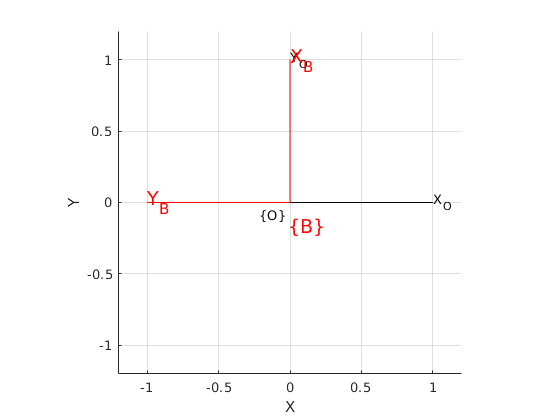


% plotting 2D graphs

figure
grid("on")
trplot2(eye(2), 'frame', 'O', 'color', 'k');

hold on;
trplot2(R, 'frame', 'B', 'color', 'r', 'text_opts', {'FontSize', 14});
hold off;


clear;

% homogeneous representation (SE2)
R = trot2(pi/3)

R =     0.5000   -0.8660         0
    0.8660    0.5000         0
         0         0    1.0000


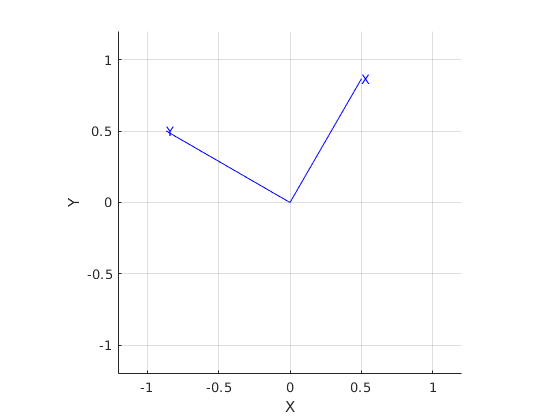


figure
grid("on")
trplot2(R);


clear;

% matrix operations
R = rot2(pi/3) * rot2(pi/6)

R =     0.0000   -1.0000
    1.0000    0.0000


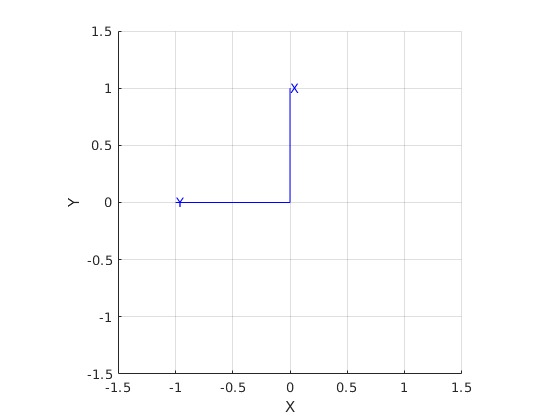


tranimate2(R, eye(2));


det_R = det(R)

det_R = 1


clear;

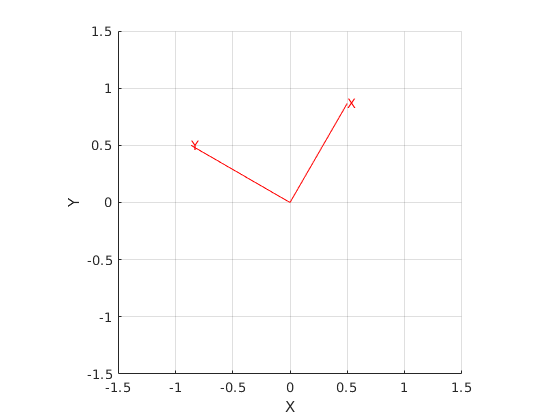

% SO2 is commutative

R1 = rot2(pi/12) * rot2(pi/4);
R2 = rot2(pi/4) * rot2(pi/12);

figure, grid("on"), tranimate2(R1, eye(2), 'color', 'r');

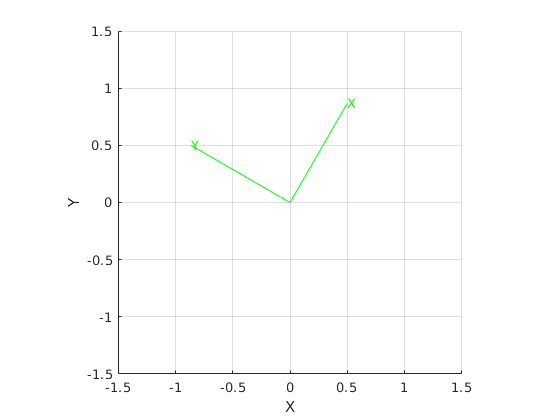



figure, grid("on"), tranimate2(R2, eye(2), 'color', 'g');


clear;

% SO2 inverse == transpose

R = rot2(3*pi/4)

R =    -0.7071   -0.7071
    0.7071   -0.7071



R_transp = R'

R_transp =    -0.7071    0.7071
   -0.7071   -0.7071


R_inverse = inv(R)

R_inverse =    -0.7071    0.7071
   -0.7071   -0.7071



clear;

% 3D rotations are represented by the SO3 class

R = SO3(eye(3))

 

R = 
         1         0         0
         0         1         0
         0         0         1



% 1. Rotate around X-axis to 90 deg
% 2. Rotate around NEW Y-axis to 60 deg
R = rotx(pi/2) * roty(pi/3)

R =     0.5000         0    0.8660
    0.8660         0   -0.5000
         0    1.0000         0


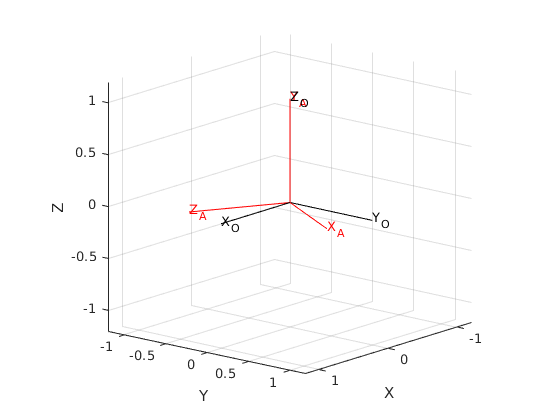


trplot(eye(3), 'frame', 'O', 'color', 'k');

hold on;
view(130, 15);
trplot(R, 'frame', 'A', 'color', 'r');
hold off;


clear;

% Again, order matters (multiplication is non-commutative for SO3)
R1 = rotx(pi/2) * roty(-pi/2)

R1 =      0     0    -1
    -1     0     0
     0     1     0


R2 = roty(-pi/2) * rotx(pi/2)

R2 =      0    -1     0
     0     0    -1
     1     0     0


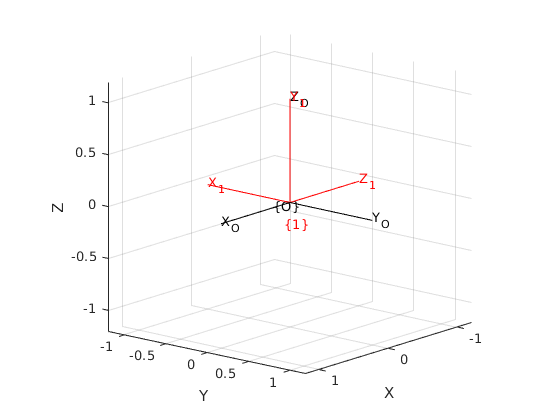


figure

trplot(eye(3), 'frame', 'O', 'color', 'k');
hold on;
trplot(R1, 'frame', '1', 'color', 'r');
view(130, 15);
hold off;

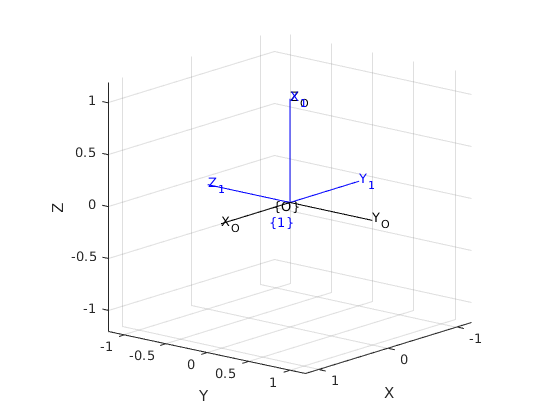


figure

trplot(eye(3), 'frame', 'O', 'color', 'k');
hold on;
trplot(R2, 'frame', '1', 'color', 'b');
view(130, 15);
hold off;


clear;

% SO3 inverse == transpose
R = rotx(pi/3) * roty(pi/2) * rotx(pi/4) * rotz(pi)

R =          0   -0.7071    0.7071
   -0.8660   -0.3536   -0.3536
    0.5000   -0.6124   -0.6124



R_transp = R'

R_transp =          0   -0.8660    0.5000
   -0.7071   -0.3536   -0.6124
    0.7071   -0.3536   -0.6124


R_inverse = inv(R)

R_inverse =     0.0000   -0.8660    0.5000
   -0.7071   -0.3536   -0.6124
    0.7071   -0.3536   -0.6124



clear;

% SO3 rotation matrix from Euler angles
R = eul2r(pi/2, pi/3, pi/4)

R =    -0.7071   -0.7071         0
    0.3536   -0.3536    0.8660
   -0.6124    0.6124    0.5000



% alternative SO3 matrix
R = rotz(pi/2) * roty(pi/3) * rotz(pi/4)

R =    -0.7071   -0.7071         0
    0.3536   -0.3536    0.8660
   -0.6124    0.6124    0.5000



clear;

R = rotx(pi/2) * roty(pi/2) * rotz(pi/2)

R =      0     0     1
     0    -1     0
     1     0     0



% convert SO3 or SE3 matrix to Euler angles
zyz_angles = tr2eul(R)

zyz_angles =          0    1.5708    3.1416



disp(rad2deg(zyz_angles))

     0    90   180




% convert back to SO3 matrix
R = eul2r(zyz_angles)

R =      0     0     1
     0    -1     0
     1     0     0



clear;

% SO3 rotation matrix from roll-pitch-yaw (RPY)
R = rpy2r(pi/3, pi/2, pi/6)

R =          0    0.5000    0.8660
         0    0.8660   -0.5000
   -1.0000         0         0



rpy = tr2rpy(R)

rpy =          0    1.5708   -0.5236



disp(rad2deg(rpy))

         0   90.0000  -30.0000




clear;

% 2D/3D rigid-body transformations (rotation and translation)
% are represented by the SE2/SE3 classes

T = SE2(eye(2), [0; 1])

 

T = 
         1         0         0
         0         1         1
         0         0         1



t = transl(T) % row-vector

t =      0     1


t = T.t       % column-vector

t =      0
     1



R = T.R

R =      1     0
     0     1



clear;

% SE2 from rotation matrix (no translation)
T = r2t(rot2(pi/3))

T =     0.5000   -0.8660         0
    0.8660    0.5000         0
         0         0    1.0000


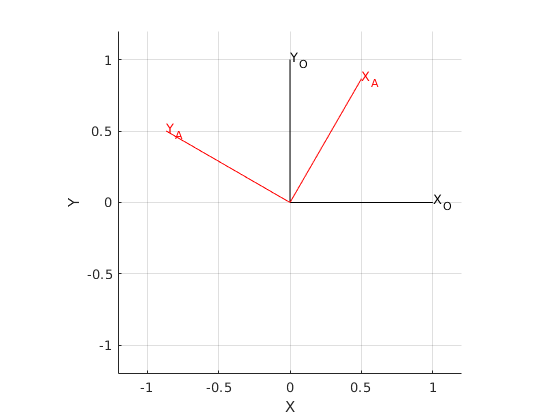


trplot2(eye(2), 'frame', 'O', 'color', 'k');
hold on;
trplot2(T, 'frame', 'A', 'color', 'r');
view(0, 90);
hold off;


% SE2 from rotation matrix and translation vector
T = rt2tr(rot2(pi/3), [3; 2])

T =     0.5000   -0.8660    3.0000
    0.8660    0.5000    2.0000
         0         0    1.0000


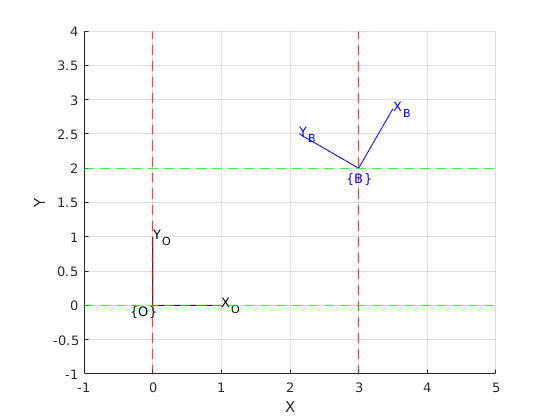


trplot2(eye(2), 'frame', 'O', 'color', 'k');

hold on;
trplot2(T, 'frame', 'B', 'color', 'b');

view(0, 90);
xlim([-1, 5])
ylim([-1, 4])
xline(0, 'r--', 'LineWidth', 1)
xline(3, 'r--', 'LineWidth', 1)
yline(0, 'g--', 'LineWidth', 1)
yline(2, 'g--', 'LineWidth', 1)

hold off;

% SE3 from rotation matrix (no translation)
T = rpy2tr(pi/2, 0, pi/3)

T =     0.5000         0    0.8660         0
    0.8660         0   -0.5000         0
         0    1.0000         0         0
         0         0         0    1.0000


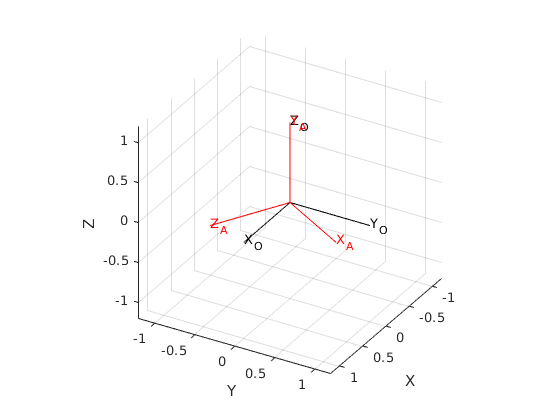


trplot(eye(3), 'frame', 'O', 'color', 'k');
hold on;
trplot(T, 'frame', 'A', 'color', 'r');
view(120, 30);
hold off;


clear;

% SE3 from rotation matrix and translation vector
T = rt2tr(rpy2r(pi/3, 0, pi/2), [1; 2; -1])

T =          0   -0.5000    0.8660    1.0000
    1.0000         0         0    2.0000
         0    0.8660    0.5000   -1.0000
         0         0         0    1.0000


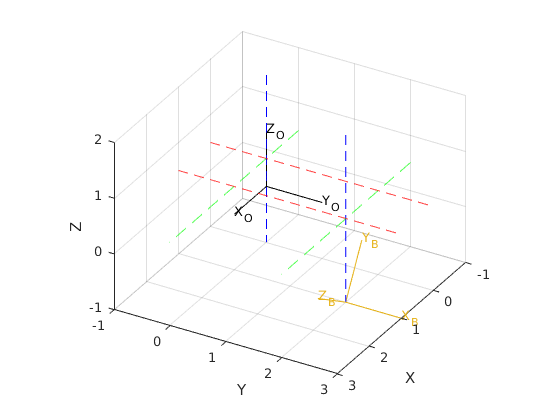


trplot(eye(3), 'frame', 'O', 'color', 'k');

hold on;
trplot(T, 'frame', 'B', 'color', [0.9 0.7 0.1]);

view(120, 30);
xlim([-1, 3])
ylim([-1, 3])
zlim([-1, 2])
xline(0, 'r--', 'LineWidth', 0.4)
xline(1, 'r--', 'LineWidth', 0.4)
yline(0, 'g--', 'LineWidth', 0.4)
yline(2, 'g--', 'LineWidth', 0.4)

plot3([0; 0], [0; 0], [-2; 2], 'b--')
plot3([1; 1], [2; 2], [-2; 2], 'b--')

hold off;


clear;

% other things
T = rt2tr(roty(pi/3) * rotx(pi/2), [1; 3; -2])

T =     0.5000    0.8660         0    1.0000
         0         0   -1.0000    3.0000
   -0.8660    0.5000         0   -2.0000
         0         0         0    1.0000



rpy = rad2deg(tr2rpy(T))

rpy =    90.0000   60.0000         0


% roll (X) -> pitch (Y') -> yaw (Z'')
R_rpy = rpy2r(pi/3, pi/4, pi/6)

R_rpy =     0.6124    0.2803    0.7392
    0.3536    0.7392   -0.5732
   -0.7071    0.6124    0.3536


R =  rotx(pi/3) * roty(pi/4) * rotz(pi/6) 

R =     0.6124   -0.3536    0.7071
    0.7803    0.1268   -0.6124
    0.1268    0.9268    0.3536
